# Automated Object Detection Using YOLO v2 Deep Learning

## **Clear Arguments**

clearvars;
clc;

## Set Arguments 

Download a pretrained detector to avoid having to wait for training to complete. If you want to train the detector, set the `doTraining` variable to true.

doTraining = true; % set true to train new network
visualizeAnchorBoxes = false; % set true to see plot of anchorbox # vs meanIoU
testDataset = true;  % set true to test new network on dataset

## Load Dataset

load the coco dataset and put it in the table format as required

%unzip bottleDatasetImages.zip
load(which('coco_dataset.mat'));

% make val2017 dataset and correct for filepaths
valDataset = images_val;
fullImageName = fullfile(sprintf('%s/val2017',pwd),valDataset(:,1));
valDataset(:,1) = fullImageName;

% repeat for train2017
trainDataset = images_train;
train_files = dir('../train2017'); %finds directory with file names
train_folder_path = train_files(1).folder;
fullImageName = fullfile(train_folder_path,trainDataset(:,1));
trainDataset(:,1) = fullImageName;

bottleDataset = [valDataset;trainDataset];
bottleDataset = cell2table(bottleDataset,...
    'VariableNames',{'imageFilename' 'bottle'});

Split the data set into a training set for training the detector, and a test set for evaluating the detector. Select 60% of the data for training. Use the rest for evaluation.

rng(0);
shuffledIndices = randperm(height(bottleDataset))

shuffledIndices =         8137        4213        7742        4928        1974        7088         609        2369        7628        7017        2874        4859         452        1582        1517        8758        5149        6285        2513        1836        3579        5697        6199        3130        3859        2890        4306        4258        8439        6954        7173        2514        7327        5664        1515        4264        5023        4715        4362        7444        2760        3915        1463        8729         123        4596        6403        8737        6495        4007


idx = floor(0.7 * length(shuffledIndices) );
trainingDataTbl = bottleDataset(shuffledIndices(1:idx),:);
testDataTbl = bottleDataset(shuffledIndices(idx+1:end),:);

Use `imageDatastore` and `boxLabelDatastore` to create datastores for loading the image and label data during training and evaluation.

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'bottle'));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'bottle'));

Combine image and box label datastores.

trainingData = combine(imdsTrain,bldsTrain);
testData = combine(imdsTest,bldsTest);
data = read(trainingData);

## Create a YOLO v2 Object Detection Network

- Network input size

- Anchor boxes

- Feature extraction network 

inputSize = [224 224 3];

Define the number of object classes to detect.

numClasses = width(bottleDataset)-1;

Note that the training images used in this example are bigger than 224-by-224 and vary in size, so you must resize the images in a preprocessing step prior to training.

Next, use  [estimateAnchorBoxes](docid:vision_ref#mw_cba7b62d-6557-41e6-9e4d-73ec50667c6d) to estimate anchor boxes based on the size of objects in the training data. To account for the resizing of the images prior to training, resize the training data for estimating anchor boxes. Use `transform` to preprocess the training data, then define the number of anchor boxes and estimate the anchor boxes. Resize the training data to the input image size of the network using the supporting function `preprocessData`. Load in the trainingDataForEstimation

trainingDataForEstimation = transform(trainingData,@(data)preprocessData(data,inputSize))

trainingDataForEstimation =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.CombinedDatastore]
             Transforms: {@(data)preprocessData(data,inputSize)}
            IncludeInfo: 0


% trainingDataForEstimation = load('trainingDataForEstimation.mat'); 

%% Find anchor boxes for this training  data

numAnchors = 15; % will use for table

**Changed from trainingData in the example to trainingDataForEstimation to put it in the correct format.**

[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =     26     7
    39    67
    79    48
    43    16
   100    29
   147    54
     9     4
   172   149
    51    29
    18    11


meanIoU = 0.6767

## Augment and Preprocess Data

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation you can add more variety to the training data without actually having to increase the number of labeled training samples.

Use `transform` to augment the training data by randomly flipping the image and associated box labels horizontally. Note that data augmentation is not applied to the test data. Ideally, test data should be representative of the original data and is left unmodified for unbiased evaluation.

augmentedTrainingData = transform(trainingDataForEstimation,@augmentData);

Read the same image multiple times and display the augmented training data.

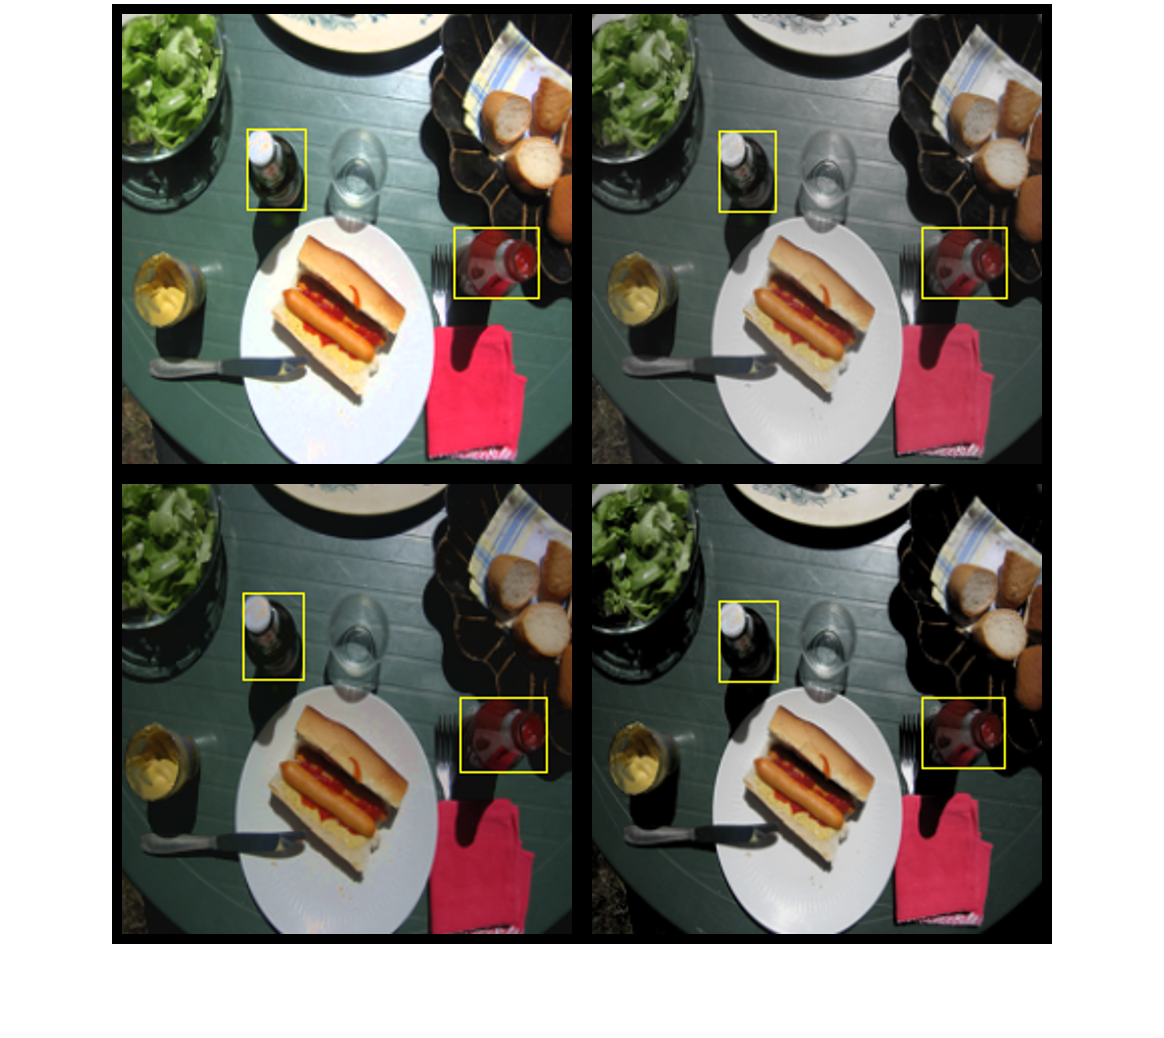

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    data{2} = correctData(data{2});
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

Once all the data is augmented to expand our dataset we can preprocess and ensure all images of are of the input size of the detector.

Preprocess the augmented training data to prepare for training.

preprocessedTrainingData = transform(augmentedTrainingData,@(data)preprocessData(data,inputSize));

Read the preprocessed training data.

data = read(preprocessedTrainingData);

Display the image and bounding boxes.

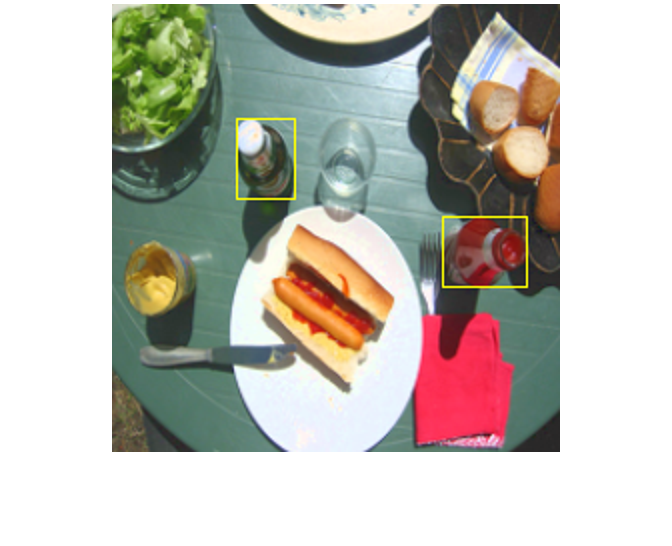

I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)

# Automation Functions

## Automated Mini-BatchSize Testing Using Object Detection Using YOLO v2 Deep Learning

## **Usage: **

To be used in automated_YOLO_Trainer.mlx. This function runs trains on a chosen network (changed by changing this function script) and measures its accuracy against different anchor box choices. To do this it makes the following assumtions:

1) Best LR is 0.001

learningRate = 1e-3; % will use for table

2) Best Anchor Box Size is 15  which have been used already to find anchor boxes in line 44. 

3) Epoch Size is 100

epochSize = 100; % will use for table

4) Solver Method 'sgdm'

solverMethod = 'sgdm';

Load in predetermined network and layer to modify.

featureExtractionNetwork = googlenet;

For googlnet we chose the following layer as it is large enough to continue the process with it

featureLayer = 'inception_5b-output'; % chosen googlenet layer
featureLayerString = string(featureLayer); % this is for adding to the table

Create the YOLO v2 object detection network. 

lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

Define array of mini batch sizes to  iterate over

miniBatchsizes = [8 16 32 64 128];


## Train YOLO v2 Object Detector

Create a for loop that iterates through the number of mini batches we want to automate.

for i = 1:length(miniBatchsizes) % will use for table
    options = trainingOptions(solverMethod, ...
            'MiniBatchSize', miniBatchsizes(i), .... % will use for table
            'InitialLearnRate',learningRate, ...
            'MaxEpochs',epochSize,...
            'CheckpointPath', tempdir, ...
            'Shuffle','never');
    [detector,info] = trainYOLOv2ObjectDetector(preprocessedTrainingData,lgraph,options);  
    saveWork = sprintf('googlenet_%d',i); % will use in table
    save(saveWork);
%     if testDataset
%         % test detector on all the testing data to see if there is any detection
%         detectedImages = 0;
%         missedImages = 0;
%         imageIndices = 1;
%         for i = 1:length(testDataTbl.imageFilename) 
%             
%             % preprocess the data for detection
%             I = imread(testDataTbl.imageFilename{i});
%             I = imresize(I,inputSize(1:2));
%             [bboxes,scores] = detect(detector,I);
%             
%             if(~isempty(bboxes))
%                 I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
%               
%                 detectedImagesIndexArray(imageIndices) = i;
%                 imageIndices = imageIndices + 1;
%                 
%                 detectedImages =  detectedImages + 1;
%             else
%                 missedImages = missedImages + 1;
%             end
%         end
%         accuracy = detectedImages/(missedImages + detectedImages) * 100; % will use to save to table
%         fprintf('total images: %d\n',length(testDataTbl.imageFilename));
%         fprintf('detected images: %d\n',detectedImages);
%         fprintf('missed images: %d\n',missedImages);
%         fprintf('Accuracy Percentage, detected/missed: %f\n',detectedImages/missedImages * 100);
%     end
%     
%     % pass through a more rigorous testing phase
%     preprocessedTestData = transform(testData,@(data)preprocessData(data,inputSize));
%     detectionResults = detect(detector, preprocessedTestData);
%     [ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedTestData); % will use for table
%     
%     load('detector_table_info.mat');
%     %print current table
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* bottle

Training on single CPU.
Initializing input data normalization.
